240032 ExFinal Q1 2021-22 Problema 2

## Problem 2

Let us consider the domain $\Omega$, meshed by means of two elements (a quadrilateral and a triangle) as follows. Nodes: $(0,0), (2,0), (5,0), (0,1), (2,1)$. Connectivity matrix: $\left(\begin{array}{cccc} 1 & 2 & 5 & 4\\ 5 & 2 & 3 & *\end{array}\right)$.

Using this mesh we are going to consider the finite element method for the following problem


$$\left\{\begin{array}{rcl}
-k_{c}\Delta u\!\!\!\! &=&\!\!\!\!\! f,\quad \text{ on }\Omega,\\
u(x,0)\!\!\!\! &=& \!\!\!\! 3x,\\
u(0,y))\!\!\!\! &=& \!\!\!\!  2y,\\
\frac{\partial u}{\partial y}(x,y) \!\!\!\! &=& \!\!\!\! 2,\quad \text{on the line joining nodes $4$ and $5$},\\
\frac{\partial u}{\partial n}(x,y) \!\!\!\! &=& \!\!\!\! 2,\quad \text{on the line joining nodes $3$ and $5$}.\\

\end{array}\right.$$


where $k_{c} = 12$, $f\equiv 2$ on $\Omega^{1}$, $f\equiv 4$ on $\Omega^{2}$.

(a) (2 points) What is the value of $\psi^{1}_{2}\left(1/2,1/2\right)$?

- 
$$3/16$$


- 
$$5/36$$


- 
$$3/8$$


- 
$$1/8$$

$$\surd$$


- Leave it empty (no penalty)

(b) (2 points) Let $K$ be the assembled natrix of the system. What is the value of $K_{5,2}$?

- 
$$-13/4$$


- 
$$-1$$


- 
$$-3/2$$


- 
$$-16$$

$$\surd$$


- Leave it empty (no penalty)

(c) (2 points) Let $F$ be the assembled force vector of the system $K U = F + Q$, what is the value of $F_{5}$?

- 
$$4$$


- 
$$2$$


- 
$$3$$

$$\surd$$


- 
$$5$$


- Leave it empty (no penalty)

(d) (2 points) What is the value $Q^{k}_{i,j} = Q^{1}_{3,3}$?

- 
$$18$$


- 
$$12$$


- 
$$36$$


- 
$$24$$

$$\surd$$


- Leave it empty (no penalty)

(e) (2 points) What is the value of $U_{5}$, the approximated solution at node $5$?

- 
$$12.78$$


- 
$$7.28$$


- 
$$6.26$$

$$\surd$$


- 
$$3.69$$


- Leave it empty (no penalty)

### Solution

First, we shall plpot the meshed domain

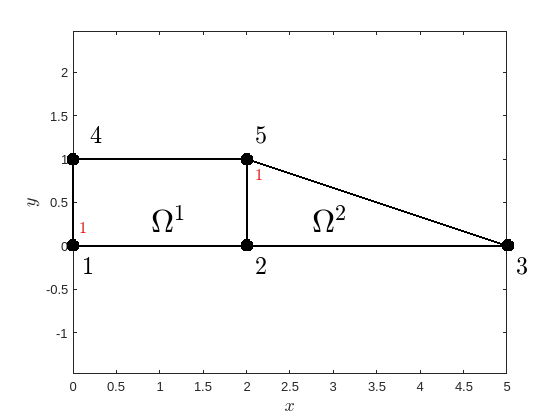

clearvars
close all

%Data
k1=12.0; f1=2;
k2=6.0; f2=4;

dudy=2.0; %on the line joining nodes 4 and 5
q1_3=k1*dudy;

nodes = [0.0 ,0.0;
    2.0, 0.0;
    5.0, 0.0;
    0.0, 1.0;
    2.0, 1.0];

elem = [1, 2, 5, 4;
    5, 2, 3, 0];

vertexs = [nodes(1,:);
    nodes(2,:); nodes(5,:); nodes(4,:); nodes(1,:)];
plot(vertexs(:,1), vertexs(:,2),'-ok','MarkerFaceColor','black',...
    'MarkerSize',8,'lineWidth',1.5)
hold on
axis equal
vertexs = [nodes(2,:); nodes(3,:); nodes(5,:)];

plot(vertexs(:,1), vertexs(:,2),'-ok','MarkerFaceColor','black',...
    'MarkerSize',8,'lineWidth',1.5)
plot(nodes(3,1), nodes(3,2),'-ok','MarkerFaceColor','black',...
    'MarkerSize', 8)

text(0.9,0.25,'$\Omega^{1}$','interpreter','LaTeX','FontSize',24)
text(2.75,0.25,'$\Omega^{2}$','interpreter','LaTeX','FontSize',24)

text(0.1,-0.25,'$1$','Interpreter','LaTeX','FontSize',18)
text(2.1,-0.25,'$2$','Interpreter','LaTeX','FontSize',18)
text(5.1,-0.25,'$3$','Interpreter','LaTeX','FontSize',18)
text(2.1,1.25,'$5$','Interpreter','LaTeX','FontSize',18)
text(0.2,1.25,'$4$','Interpreter','LaTeX','FontSize',18)

text(0.07,0.2,'$1$','Interpreter','LaTeX','FontSize',12,'Color','red')
text(2.1,0.8,'$1$','Interpreter','LaTeX','FontSize',12,'Color','red')
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$y$','Interpreter','latex','FontSize',14)
hold off

(a) Recall that the shape funcitons **for rectangles **(see figure below, left), are:

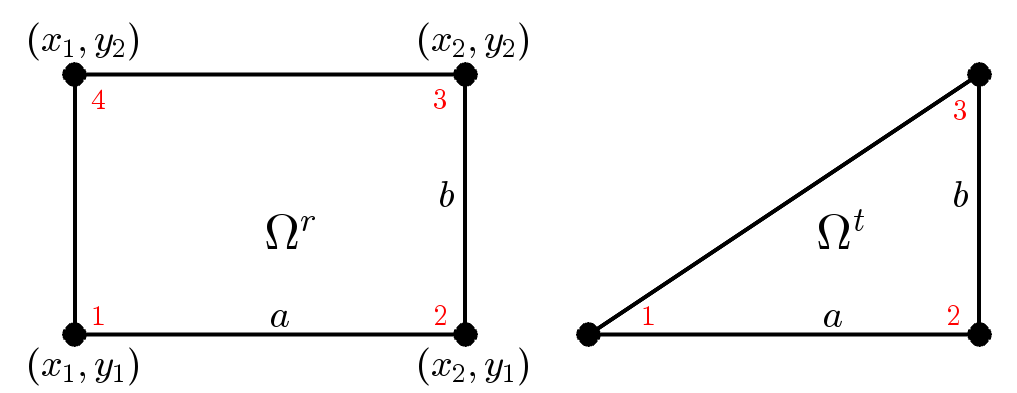

%Rectangle: elem 1 
vertexsR=nodes(elem(1,:),:);
a = norm(vertexsR(2,:)-vertexsR(1,:));
b = norm(vertexsR(4,:)-vertexsR(1,:));

%Shape functions for rectangles
Psi1=@(x,y) (x-vertexsR(2,1))*(y-vertexsR(3,2))/a/b;
Psi2=@(x,y) -(x-vertexsR(1,1))*(y-vertexsR(3,2))/a/b;
Psi3=@(x,y) (x-vertexsR(1,1))*(y-vertexsR(1,2))/a/b;
Psi4=@(x,y) -(x-vertexsR(2,1))*(y-vertexsR(1,2))/a/b;


 **Part (a).** For the rectangle of the figure $x_{2} > x_{1}$, and $y_{2} > y_{1}$ (element $\Omega^{r}$). If we denote $\left\{\begin{array}{c} a = x_{2} - x_{1}\\ b = y_{2} - y_{1}\end{array}\right\}$, then the shape funcions are


$$\begin{array}{rcl}
\psi^{r}_{1}(x,y)\!\!\!\! &=&\!\!\!\!\! \frac{1}{a b}\left(x-x_{2})(y-y_{2}\right),\\
\psi^{r}_{2}(x,y)\!\!\!\! &=&\!\!\!\!\! -\frac{1}{ab}\left(x-x_{1}\right)\left(y-y_{2}\right),\\
\psi^{r}_{3}(x,y)\!\!\!\! &=&\!\!\!\!\! \frac{|}{ab}\left(x-x_{1}\right)\left(y-y_{1}\right),\\
\psi^{r}_{4}(x,y)\!\!\!\! &=&\!\!\!\!\! -\frac{a}{b}\left(x-x_{2}\right)\left(y-y_{1}\right).
\end{array}$$


In our case, and according to the notation of the figure $(x_{1}, y_{1}) = (0.0)$, $(x_{2}, y_{2}) = (2,1)$, $a = 2$, $b = 1$; so the shape function associated to the second node of the first element ($r = 1$) is, 


$$\psi^{1}_{2}(x,y) =- \frac{\left(x-0\right)\left(y-1\right)}{2} = -\frac{x\left(y-1\right)}{2}$$


and therefore: $\psi^{1}_{2}\left(1/2,1/2\right) = -\frac{1/2\left(-1/2\right)}{2} = \frac{1}{8}$. So the solution is $\psi^{1}_{2}\left(\frac{1}{2},\frac{1}{2}\right) = \frac{1}{8}$.

dudy=2.0; %on the line joining nodes 4 and 5
q1_3=k1*dudy; 

%Rectangle: elem 1 
vertexsR=nodes(elem(1,:),:);
a = norm(vertexsR(2,:)-vertexsR(1,:));
b = norm(vertexsR(4,:)-vertexsR(1,:));

Psi1=@(x,y) (x-vertexsR(2,1))*(y-vertexsR(3,2))/a/b;
Psi2=@(x,y) -(x-vertexsR(1,1))*(y-vertexsR(3,2))/a/b;
Psi3=@(x,y) (x-vertexsR(1,1))*(y-vertexsR(1,2))/a/b;
Psi4=@(x,y) -(x-vertexsR(2,1))*(y-vertexsR(1,2))/a/b;

**Part (b)** Recall, on the one hand that, if the coefficients in the model equation, $a_{11}$, $a_{12}$, $a_{21}$, $a_{22}$, $a_{00}$, are constants on the *r*ectangular element $\Omega^{r}$, we write $a_{11}\equiv a^{r}_{11}$, $a_{12}\equiv a^{r}_{12}$, $a_{21}\equiv a^{r}_{21}$, $a_{22} \equiv a^{r}_{22}$, $a_{00} = a^{r}_{00}$; then the local stiffnesss matrix, $K^{r}$, is given by the sum


$$K^{r} = K^{r,11} + K^{r,12} + K^{r,21} + K^{r,22} + K^{r,00},$$


with


$$\begin{array}{ll}
K^{r,11}=\frac{ba_{11}^{r}}{6a}\left(\begin{array}{rrrr}
2 & -2 & -1 & 1\\
-2 & 2 & 1 & -1\\
-1 & 1 & 2 & -2\\
1 & -1 & -2 & 2
\end{array}\right), &\qquad\qquad
K^{r,12} = \frac{a^{r}_{12}}{4}\left(\begin{array}{rrrr}
1 & 1 & -1 & -1\\
-1 & -1 & 1 & 1\\
-1 & -1 & 1 & 1\\
1 & 1 & -1 & -1
\end{array}\right),\\ \\
K^{r,22} = \frac{a a^{r}_{22}}{6b}\left(\begin{array}{rrrr}
2 & 1 & -1 & -2\\
1 & 2 & -2 & -1\\
-1 & -2 & 2 & 1\\
-2 & -1 & 1 & 2
\end{array}\right), &\qquad\qquad
K^{r,00} = \frac{a b a^{r}_{00}}{36}\left(\begin{array}{rrrr}
4 & 2 & 1 & 2\\
2 & 4 & 2 & 1\\
1 & 2 & 4 & 2\\
2 & 1 & 2 & 4
\end{array}\right).
\end{array}$$


We shall often assume that $a^{r}_{12} = a^{r}_{21}$. In such case one sees straight (from the integrals that give their components) that $K^{r,21} = \left(K^{r,12}\right)^{\top}$and, in particular, the matrix $K^{r}$ is symmetric. Besides, if the rhs of the PDF, $f$ is constant on $\Omega^{r}$, $f\equiv f^{r}$, the vector $F^{r}$is given by


$$F^{r} = \frac{ab}{4} \left(\begin{array}{c}
1\\ 1\\ 1\\ 1
\end{array}\right).$$


On the other hand, for right triangle elements (see triange element in the Figure above, element $\Omega^{t}$) and the Poisson equation with constant coefficients on the element, i.e., $a_{11}\equiv a^{t}_{11} = a^{2}_{22} = c$, $a^{r}_{12} = a^{r}_{21} = a^{r}_{00} = 0$. *If the second local node is placed at the right angle* (as in the Figure), the stiffness matrix is given by,


$$K^{t} = \frac{c}{2ab}\left(\begin{array}{rcr}
b^{2} & -b^{2} & 0\\
-b^{2} & a^{2} + b^{2} & -a^{2}\\
0 & -a^{2} & a^{2}
\end{array}\right).
$$


If further we assume that the rhs of the PDE, $f$, is constant on the triangle element $\Omega^{t}$, $f\equiv f^{t}$, then the vector $F^{t}$ is given by


$$F^{t} = \frac{a b\!f^{t}}{6}\left(\begin{array}{c}
1 \\ 1 \\ 1
\end{array}\right),$$


where now, $a$ is the length of the edge of the triangle connecting the local nodes $1$ and $2$, and $b$ is the length of the edge of the triangle connecting the local nodes $2$ and $3$. In the problem at hand,

- For the rectangle, $\Omega^{1}$, $r = 1$, $a = 2$, $b = 1$, $a^{1}_{11} = a^{1}_{22} = 12$, $a^{1}_{12} = a^{1}_{21} = a^{1}_{00} = 0$, and $f^{1} = 2$, so


$$K^{1} = \frac{12}{12}\left(\begin{array}{rrrr} 2 & -2 & -1 & 1\\ -2 & 2 & 1 & -1\\ -1 & 1 & 2 & -2\\ 1 & -1 & -2 & 2\end{array}\right) + \frac{2\cdot 12}{6}\left(\begin{array}{rrrr} 2 & 1 & -1 & -2\\ 1 & 2 & -2 & -1\\ -1 & -2 & 2 & 1\\ -2 & -1 & 1 & 2 \end{array}\right) = \left(\begin{array}{rrrr} 10 & 2 & -5 & -7\\ 2 & 9 & -7 & -5\\ -5 & -7 & 10 & 2\\ -7 & -5 & 2 & 10\end{array}\right),\qquad F^{1} = \frac{2\cdot 2}{4}\left(\begin{array}{c} 1\\ 1\\ 1\\ 1\end{array}\right) = \left(\begin{array}{c} 1\\ 1\\ 1\\ 1\end{array}\right)$$


- For the triangle, 

%Stifness Matrix
A=[2,-2,-1, 1;
  -2, 2, 1,-1;
  -1, 1, 2,-2;
   1,-1,-2, 2];

B=[2, 1,-1,-2;
   1, 2,-2,-1;
  -1,-2, 2, 1;
  -2,-1, 1, 2];


K=b*k1*A/a + a*k1*B/b;
K=K/6;

F=0.25*f1*a*b*[1;1;1;1];

Q1_33=q1_3*a/2; 

%Triangle: elem 2
vertexsT=nodes(elem(2,1:3),:);
a=norm(vertexsT(2,:)-vertexsT(1,:));
b=norm(vertexsT(3,:)-vertexsT(2,:));

b2=b*b;
a2=a*a;

A=[b2,   -b2,    0; 
  -b2, a2+b2,  -a2;
    0,   -a2,   a2];

L=0.5*k2*A/a/b;

G=f2*a*b*[1;1;1]/6;

%Natural B.C;
Q2_13=0.0; %q2_3=0 on the line joining nodes 3 and 5
Q5=Q1_33+Q2_13;

%Essential B.C.
U1=0.0;
U2=3*nodes(2,1);
U3=3*nodes(3,1);
U4=2*nodes(4,2);
um=[U1;U2;U3;U4];
k=[0.0,K(3,2)+L(1,2),0.0,K(3,4),K(3,3)+L(1,1)];
U5=(F(3)+G(1)+Q5-k(1:4)*um)/k(5); 
    

%Solutions
clc
  fprintf( ...
   ['====================================================\n',...
    '                       PROB.2                       \n',...
    '====================================================\n',...
    '********************** PART A **********************\n',...
    'Psi1(2;0.5,0.5) = %.5e\n',...
    '********************** PART B **********************\n',...
    'K(5,2) = %.5e\n',...
    '********************** PART C **********************\n',...
    'F(5) = %.5e\n',... 
    '********************** PART D **********************\n',...
    'Q1_33 = %.5e\n',... 
    '********************** PART E **********************\n',...
    'U(5) = %.5e\n',...
    '****************************************************\n'],...
    Psi2(0.5,0.5), K(3,2)+L(1,2),F(3)+G(1),Q1_33,U5 ...
    )

                       PROB.2                       
********************** PART A **********************
Psi1(2;0.5,0.5) = 1.25000e-01
********************** PART B **********************
K(5,2) = -1.60000e+01
********************** PART C **********************
F(5) = 3.00000e+00
********************** PART D **********************
Q1_33 = 2.40000e+01
********************** PART E **********************
U(5) = 6.26316e+00
****************************************************
